# DDE Oscillator & Toogle Switch

## DDEs of Synthetic Oscillator

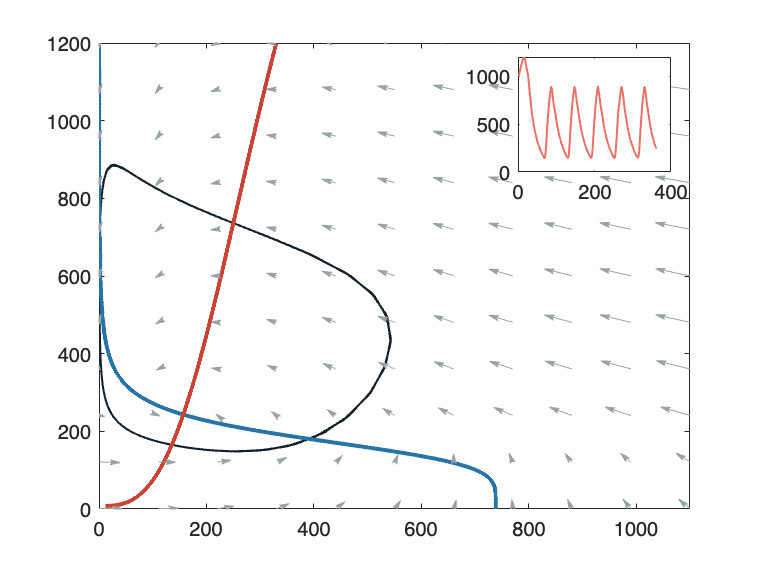

clear
%==================limit cycle=================
lags = [1 2];
tspan = linspace(0,80,100);
y0 = [600,1000];
sol = dde23(@pn,lags,@(t)yhist(t,y0),tspan);

t=sol.x;
y=sol.y;
hold on
p1 = plot(y(1,60:end),y(2,60:end));
p1.LineWidth = 1;
p1.Color = '#17202A';%'#3498DB';
box on

%=================nullcline=====================
hold on
max_x = 1100;
max_y = 1200;
x_lim = [0,max_x];
y_lim = [0,max_y];
[H_null,S_null]=nullcline(x_lim,y_lim);

p2 = plot(H_null(:,1),H_null(:,2));
p2.LineWidth = 2;
p2.Color = '#2874A6';
p2.LineStyle = '-';
p3 = plot(S_null(:,1),S_null(:,2));
p3.LineWidth = 2;
p3.Color = '#CB4335';
p3.LineStyle = '-';


%===================quiver======================

%%


xList=linspace(1,max_x,11);
yList=linspace(1,max_y,11);
U=[];
V=[];
[X, Y] = meshgrid(xList, yList);
ts = 1:2;
LineLength=0.06;
for i=1:length(X)
    for j=1:length(Y)
        y00=[X(i,j),Y(i,j)];
        sol = dde23(@pn,lags,@(t)yhist(t,y00),ts);
        t=sol.x;
        y=sol.y;
        U(i,j)=y(1,end)-y(1,1);
        V(i,j)=y(2,end)-y(2,1);
        ah = annotation('arrow','headStyle','cback2','Color','#99A3A4','HeadLength',5,'HeadWidth',2.5);
        set(ah,'parent',gca);
        ah.Position=[X(i,j),Y(i,j),U(i,j)*LineLength,V(i,j)*LineLength];
    end
end
% quiver(X, Y, U, V,0.5,'Color','#99A3A4');
ylim([0,max_y]);
xlim([0,max_x]);

%% =================time traj=====================
axes('Position',[.68 .7 .2 .2])
tspan = linspace(0,80,100);
y0 = [600,1000];
sol = dde23(@pn,lags,@(t)yhist(t,y0),tspan);

t=sol.x;
y=sol.y;
p4 = plot(y(2,1:end));
p4.LineWidth = 1;
p4.Color = '#EC7063';


function dydt = pn(t,y,Z)
    ylag1 = Z(:,1);
    ylag2 = Z(:,2);
    
    as = 30.5;
    ah = 183;
    ah0 = 0.1;
    as0 = 0.1;
    beta = 4.6;
    dm = 0.3;
    dh = 3.8;
    ds = 0.2;
    Kh = 326;
    Ks = 185;
%     Khs=30;
    n1 = 3;
    n2 = 4.8;
    K = beta/dm;
    dydt = [K*ah0 + K*ah*Ks^n2/(Ks^n2+ylag2(2)^n2)-dh*y(1); %dHdt
            K*as0 + K*as*ylag1(1)^n1/(Kh^n1+ylag1(1)^n1)-ds*y(2);  %dSdt
        ];
%         dydt = [K*a0 + K*ah*Ks^n2/(Ks^n2+ylag2(2)^n2)*ylag1(1)^n1/(Khs^n1+ylag1(1)^n1)-dh*y(1); %dHdt
%             K*as*ylag1(1)^n1/(Kh^n1+ylag1(1)^n1)-ds*y(2);  %dSdt
%         ];
    
end


function s=yhist(t,y0)
    s = y0; %sir2,HAP
end

function [H_null,S_null]=nullcline(xlim,ylim)
    steps = 2000;
    x_list = linspace(xlim(1),xlim(2),steps+1);
    y_list = linspace(ylim(1),ylim(2),steps+1);
    m=1;
    n=1;
    for i=2:length(x_list)
        xitem_1 = x_list(i-1);
        xitem_2 = x_list(i);
        
        for j=2:length(y_list)
            yitem_1 = y_list(j-1);
            yitem_2 = y_list(j);
            
            [x1,y1] = quiver_(xitem_1,yitem_1);
            [x2,y2] = quiver_(xitem_2,yitem_1);
            if sign(x1)~=sign(x2)
                H_null(m,1) = xitem_1; 
                H_null(m,2) = yitem_1; 
                m=m+1;
            elseif sign(y1)~=sign(y2)
                S_null(n,1) = xitem_1; 
                S_null(n,2) = yitem_1;
                n=n+1;
            end
        end
    end
            
end

function [u,v]=quiver_(H,S)
    as = 30.5;
    ah = 183;
    ah0 = 0.1;
    as0 = 0.1;
    beta = 4.6;
    dm = 0.3;
    dh = 3.8;
    ds = 0.2;
    Kh = 326;
    Ks = 185;
%     Khs=30;
    n1 = 3;
    n2 = 4.8;
    K = beta/dm;
    u = K*ah0 + K*ah*Ks.^n2./(Ks^n2+S.^n2)-dh*H;
    v =  K*as0+K*as*H.^n1./(Kh^n1+H.^n1)-ds*S;
end

## Toogle Switch

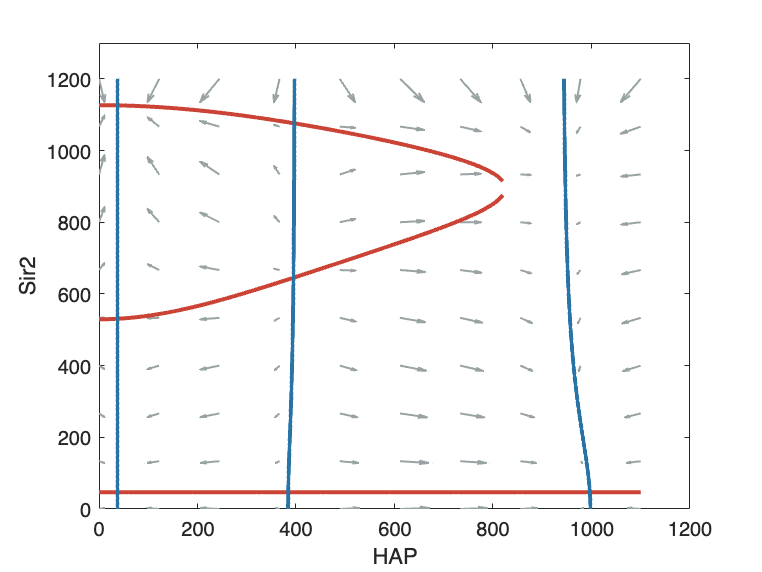

close all
clear

%% set parameters
k_hap_prod = 80;
k_hap_deg = 0.08;
k_hap_prod_base = 3; %hap4 leftmost line
KM_SonH = 328;
KM_pos = 450; %hap4 mid line

Total = 1200;
k_sir_prod = 42;
k_sir_deg = 0.015;
KM_HonS =400;
KM_pos2 = 4180; %sir2 u shape
k_sir_prod_base = 0.7; %sir2 bottom line

n1 = 4;
n3 = 4;
n4 = 2;

neg_strength1 = 0.35;
neg_strength2 = 0.95;

%%
%% get the vector for quiver plot, and save data for later plotting with python 
figure
h_2 =linspace(0,1100,10);
s_2 =linspace(0,Total,10);
[X, Y] = meshgrid(h_2,s_2);

neg_fac = (neg_strength1*X.^n4+KM_HonS^n4)./(X.^n4+KM_HonS^n4);
ds = k_sir_prod*neg_fac.*(Y.^n3./(Y.^n3+KM_pos2^n3)).*(Total-Y) + k_sir_prod_base - k_sir_deg*Y;

neg_fac2 = (neg_strength2*Y.^n4+KM_SonH^n4)./(Y.^n4+KM_SonH^n4);
dh = k_hap_prod*neg_fac2.*(X.^n3./(X.^n3+KM_pos^n3)) + k_hap_prod_base - k_hap_deg*X;
% 
%  ylim([0 1210])
%  xlim([0,1110])

box on
hq = quiver(X,Y,dh,ds,0.9,'Color','#99A3A4');
hq.AutoScaleFactor=0.5;
hq.LineWidth=1;
xlabel('HAP');
ylabel('Sir2')


LineLength=4;
% 
% for i=1:size(X,1)
%     for j=1:size(X,2)
%         ah = annotation('arrow','headStyle','cback2','Color','#99A3A4','HeadLength',5,'HeadWidth',2.5);
%         set(ah,'parent',gca);
%         ah.Position=[X(i,j),Y(i,j),dh(i,j)*LineLength,ds(i,j)*LineLength];
%         
%     end
% end
hold on
%% find the sir2 roots at steady state
for ii = 0:110
    h(ii+1) = ii*10;
    neg_fac = (neg_strength1*h(ii+1)^n4+KM_HonS^n4)/(h(ii+1)^n4+KM_HonS^n4);
    s_roots(ii+1,:) = roots([(-k_sir_prod*neg_fac - k_sir_deg) (k_sir_prod*neg_fac*Total+k_sir_prod_base) 0 0 -k_sir_deg*KM_pos2^4  k_sir_prod_base*KM_pos2^4]);

end
%% get rid of imaginary roots
image_roots = abs(imag(s_roots))>3;
s_roots2 = s_roots;
s_roots2(image_roots) = nan;
s_line = real(s_roots2);
h_line = h;
p1=plot(h_line, s_line,  'Color',' #CB4335', 'LineWidth', 2);
% yticks([0,200,400,600,800,1000,1200])
 ylim([0 Total+100])
%  xlim([0,1100])
hold on

%% find the hap roots at steady state
for ii = 0:Total
    s(ii+1) = ii;
    neg_fac2 = (neg_strength2*s(ii+1)^n4+KM_SonH^n4)/(s(ii+1)^n4+KM_SonH^n4);
    h_roots(ii+1,:) = roots([(-k_hap_deg) (k_hap_prod_base+k_hap_prod*neg_fac2) 0 0 -k_hap_deg*KM_pos^4  k_hap_prod_base*KM_pos^4]);
end






%% get rid of imaginary roots
image_roots = abs(imag(h_roots))>80;
h_roots2 = h_roots;
h_roots2(image_roots) = nan;
h_line2 = real(h_roots2);
s_line2 = s;
plot(h_line2,s_line2, 'Color',' #2874A6', 'LineWidth', 2)


%%
save('./ts.mat', 'X','Y', 'dh', 'ds', 's_line', 'h_line', 's_line2', 'h_line2', '-v7.3');
% print(gcf, '-dpdf', '-r1000', 'toggle_phase')